# VENTANEO 

### Ventana Cuadrada

En esta seccion creamos una venta primero creamos zeros y luego ponemos unos en un rango 

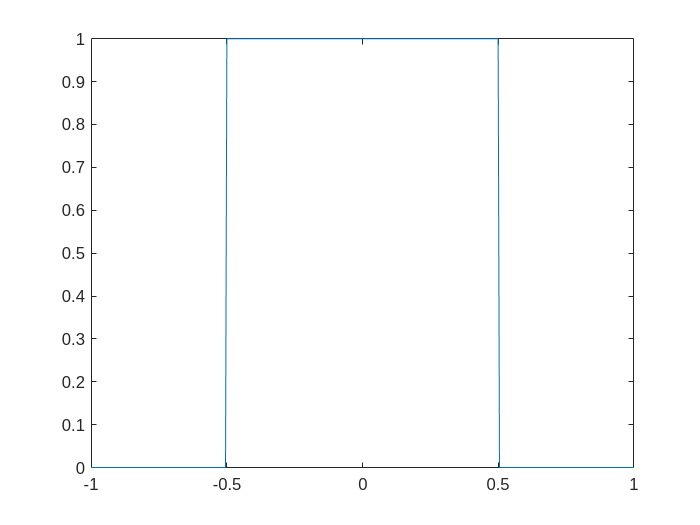

close all;
frec=-1:1/200:1;
lenf=length(frec);
x=zeros(1,lenf);
x(101:301)=1;
plot(frec,x);

### Ventana de hamming

Usaremos la ventan cuadrada y hacemos un ventana de hamming del mismo tamaño esto se usara para comparar despues. 

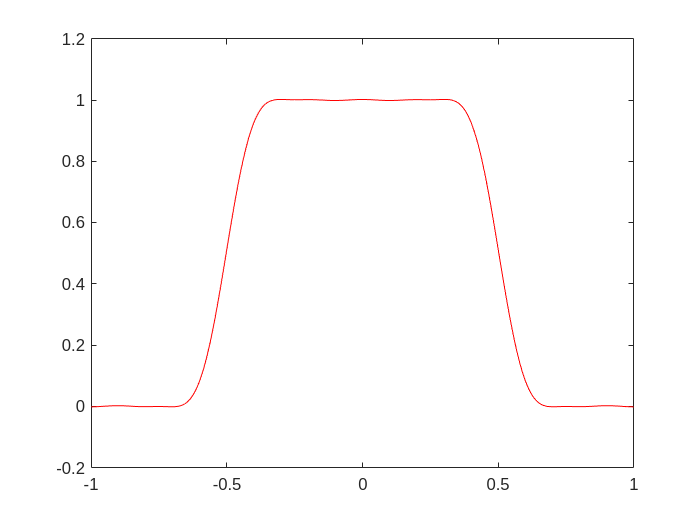

x = int32(x);
y=real(ftot(x));
ventanahamm=zeros(1,lenf);
ventanahamm(191:211)=hamming(21); %Ventana Hamming con valor hasta 21
filtro=y.*ventanahamm;
plot(frec,real(ttof(filtro)), 'r');